clear all
close all
load Module2.mat
sl_range = max(ALT.sl)-min(ALT.sl);
sl_range = squeeze(sl_range);
t = ALT.t;
lat = ALT.lat;
long = ALT.lon;

### **The following determines boundaries of Pacific region needed**

[lon_west,loni_west] = min(abs(ALT.lon-160))

lon_west = 0.1250

loni_west = 31

[l_west,lat_west] = min(abs(ALT.lat-0))

l_west = 0.1250

lat_west = 61

[lon_east,loni_east] = min(abs(ALT.lon-270))

lon_east = 0.1250

loni_east = 141

[l_east,li_east] = min(abs(ALT.lat-0))

l_east = 0.1250

li_east = 61

size(ALT.sl)

ans =    311   121   161


### **Q1 We use squeeze to plot the time series of 160W & 270W region**

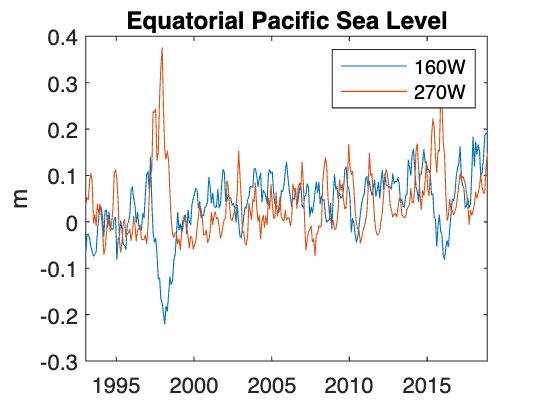

clf
plot(t,squeeze(ALT.sl(:,61,loni_west)));
hold on
plot(t,squeeze(ALT.sl(:,61,loni_east)));
title('Equatorial Pacific Sea Level')
legend('160W', '270W')
ylabel('m')
hold off

### **Ans 2 The Hovmuller plot using contourf which creates vectors of =sea level over region**

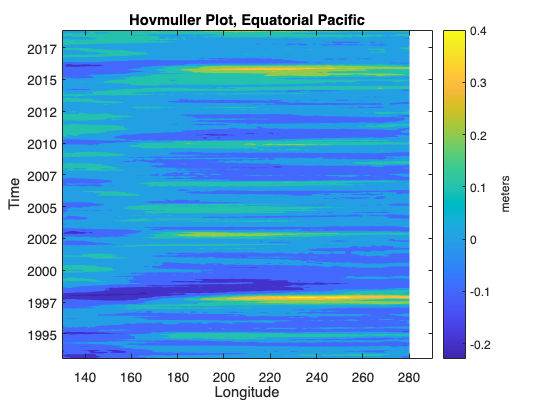

eq = find(ALT.lat == min(abs(ALT.lat)));
figure
contourf(ALT.lon,datenum(t),squeeze(ALT.sl(:,eq,:)),'Linecolor','none')
datetick('y',10,'keeplimits');
cb = colorbar;
title('Hovmuller Plot, Equatorial Pacific')
ylabel('Time');
ylabel(cb,'meters');
xlabel('Longitude');

[nt,nlat,nlon] = size(ALT.sl);
sl_season = NaN(12,nlat,nlon);
[yr,mo,dy] = datevec(ALT.t);
sla = ALT.sl;
for j = 1:12
    sl_season(j,:,:) = mean(ALT.sl(mo==j,:,:));
end

### **Ans 3 Calculating sea level anomaly and removing seasonal variabilty**

for j = 1:nt
    sla(j,:,:) = sla(j,:,:) - sl_season(mo(j),:,:);
end

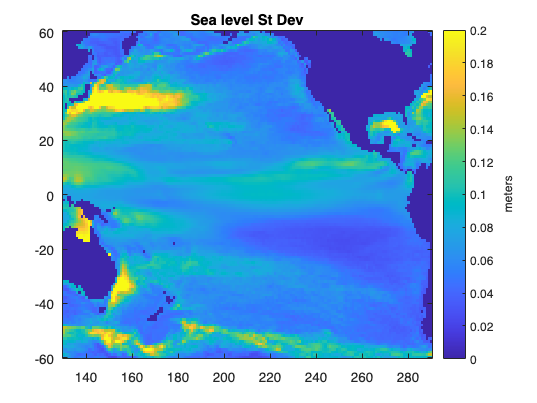

std_sl = squeeze(std(ALT.sl,'omitnan'));
imagesc(long,lat,std_sl)
set(gca,'YDir','normal')
title('Sea level St Dev')
cb = colorbar;
caxis([0 .2])
ylabel(cb,'meters');

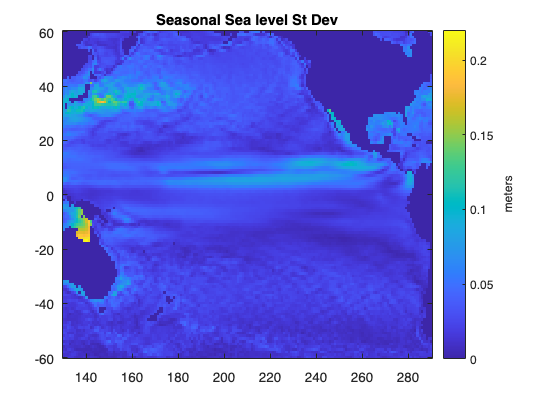

std_sl = squeeze(std(sl_season,'omitnan'));
imagesc(long,lat,std_sl)
set(gca,'YDir','normal')
title('Seasonal Sea level St Dev')
cb = colorbar;
ylabel(cb,'meters');

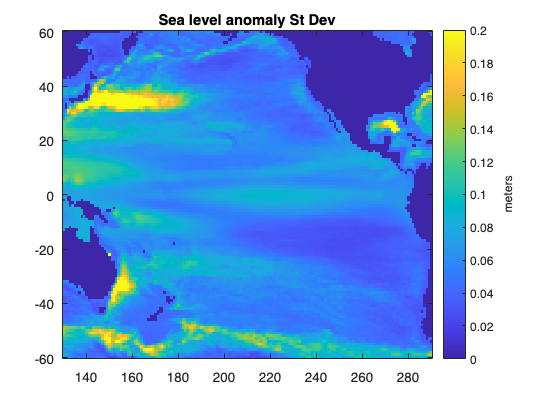

std_sl = squeeze(std(sla,'omitnan'));
imagesc(ALT.lon,ALT.lat,std_sl)
set(gca,'YDir','normal')
title('Sea level anomaly St Dev')
cb = colorbar;
ylabel(cb,'meters');
caxis([0 .2])

nyears = yr(end)-yr(1)+1

nyears = 26

sl_annual = NaN(nyears, nlat, nlon);
for j= 1:nyears
    sl_annual(j,:,:) = mean(sla(yr==yr(j),:,:));
end

#### Ans 4 Regressing the annual sea level over years gives slopes at each grid point

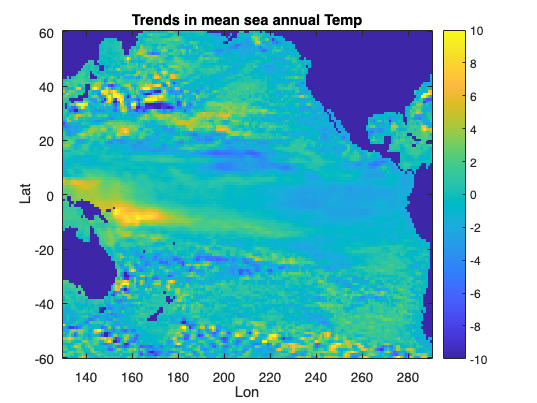

slopes = NaN(nlat,nlon);
conf_95 = NaN(nlat,nlon);
x = [(1:nyears)' ones(nyears,1)];
for j2 = 1:nlon
    for j1 =1:nlat
        y = squeeze(sl_annual(:,j1,j2));
        if ~isnan(mean(y))
            [b,bint] = regress(y,x);
            slopes(j1,j2) = b(1)*1000;
            conf_95(j1,j2) = (bint(1,2)-bint(1,1))/2*1000;
        end
    end
end
imagesc(long,lat, slopes);
set(gca,'YDir','normal');
title('Trends in mean sea annual Temp');
xlabel('Lon');
ylabel('Lat');
cb = colorbar;
caxis([-10 10])

slopes = NaN(nlat,nlon);
conf_95 = NaN(nlat,nlon);
x = [(1993:2018)' ones(nyears,1)];
for j2 = 1:nlon
    for j1 =1:nlat
        y = squeeze(sl_annual(:,j1,j2));
        if ~isnan(mean(y))
            [b,bint] = regress(y,x);
            slopes(j1,j2) = b(1)*1000;
            conf_95(j1,j2) = (bint(1,2)-bint(1,1))/2*1000;
        end
    end
end
imagesc(long,lat, slopes);
set(gca,'YDir','normal');
title('Trends in mean sea annual Temp');
xlabel('Lon');
ylabel('Lat');
cb = colorbar;
caxis([-10 10])

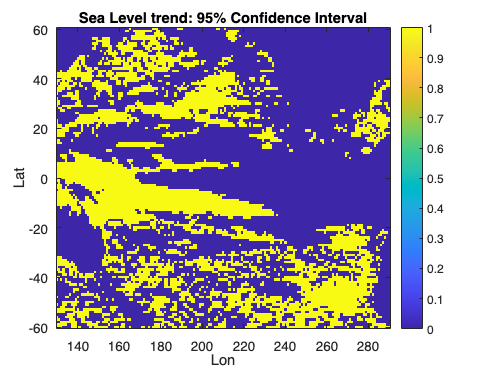

%conf_arr = zeros(size(conf_95));
%k = find(slopes>conf_95);
%conf_arr(k) = 1;
imagesc(long,lat, slopes>conf_95);
set(gca,'YDir','normal');
title('Sea Level trend: 95% Confidence Interval');
xlabel('Lon');
ylabel('Lat');
cb = colorbar;

%sla = ALT.sl;
%for j = 1:nt
   % sla(j,:,:) = sla(j,:,:) - sl_season(mo(j),:,:);
%end

#### Ans 5 -6 The detrended sea level anomaly is correlated with ONI index.

#### p-value of 95% confidence interval is plotted

#### The gain plot corresponds to correlation plot :

#### Since regions in equatorial pacific have high correlation, The magnitude of gain is higher for those regions. However, the intensity of difference is reduced for gain. This suggests that Sea level does have ONI as a proxy but not the only one.

[nt,nlat,nlon] = size(ALT.sl);
sl_cor = NaN(nlat,nlon);
sl_p = NaN(nlat,nlon);
for jlon = 1:nlon
    for jlat = 1:nlat
        if(~isnan(mean(sla(:,jlat,jlon))))
            sla_detrend = detrend(sla(:,jlat,jlon));
            [r,p] = corr(detrend(sla(:,jlat,jlon),'omitnan'),ONI);
            sl_cor(jlat,jlon) = r;
            sl_p(jlat,jlon) = p;
        end
    end
end

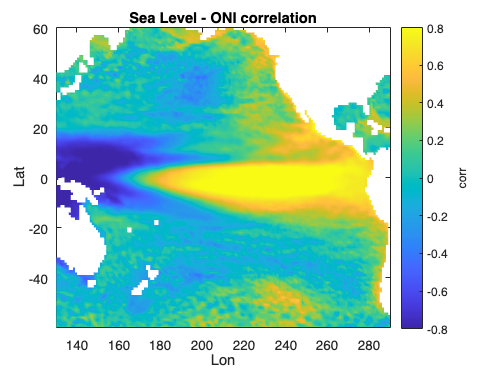

pcolor(ALT.lon,ALT.lat,sl_cor)
%set(gca,'YDir','normal')
xlabel('Lon')
ylabel('Lat')
title('Sea Level - ONI correlation')
cb = colorbar;
ylabel(cb,'corr')
caxis([-.8 .8])
shading interp

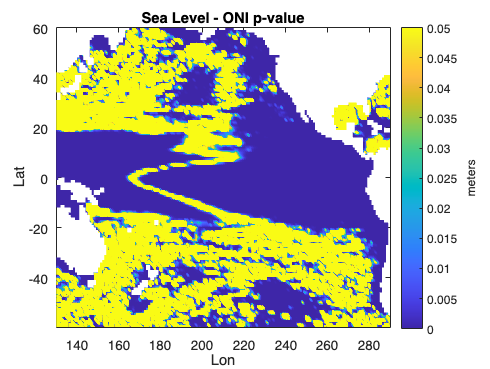

pcolor(ALT.lon,ALT.lat,sl_p)
%set(gca,'YDir','normal')
xlabel('Lon')
ylabel('Lat')
title('Sea Level - ONI p-value')
cb = colorbar;
ylabel(cb,'meters')
caxis([0 .05])
shading interp

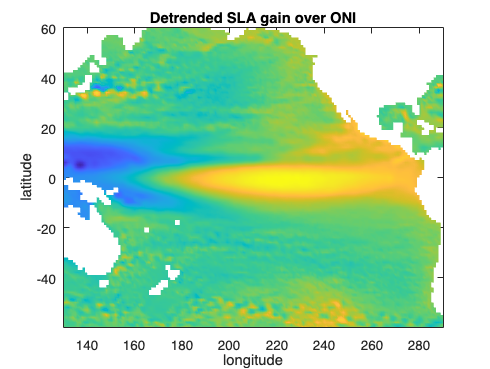

warning('off')
x = [ONI ones(size(ONI))];
for j2 = 1:nlon
    for j1 =1:nlat
        sla_detrended(j2,j1,:) = detrend(sla(:,j1,j2),1);
        [B,bint] = regress(squeeze(sla_detrended(j2, j1,:)),ONI);
        sl_gain(j2,j1) = B(1);
    end
end
sl_gain(find(sl_gain==0))=nan;
figure
pcolor(ALT.lon,ALT.lat,sl_gain')
shading interp
title('Detrended SLA gain over ONI');
xlabel('longitude');
ylabel('latitude');

pcolor(ALT.lon,ALT.lat,sl_gain)
%set(gca,'YDir','normal')
xlabel('Lon')
ylabel('Lat')
title('Sea Level - ONI gain')
cb = colorbar;
ylabel(cb,'corr')
caxis([-.8 .8])
shading interp

%sl_gain = sla_trend ./ ONI
for j = 1:12
    imagesc(ALT.lon,ALT.lat,squeeze(sl_season(j,:,:)));
    set(gca,'YDir','normal')
    xlabel('Lon')
    ylabel('Lat')
    title(['Month ',num2str(j)]);
    cb = colorbar;  
    ylabel(cb,'meters')           
    caxis([-.2 .2])
    pause (.5)
end